# Simscape multibody model of Regbot in balance

initial setup with motor velocity controller this is intended as simulation base for balance control.

close all
clear

## Simulink model name

model='regbot_1mg';

## parameters for REGBOT

motor

RA = 3.3/2;    % ohm (2 motors)
JA = 1.3e-6*2; % motor inertia
LA = 6.6e-3/2; % rotor inductor (2 motors)
BA = 3e-6*2;   % rotor friction
Kemf = 0.0105; % motor constant
Km = Kemf;
% køretøj
NG = 9.69; % gear
WR = 0.03; % wheel radius
Bw = 0.155; % wheel distance
% 
% model parts used in Simulink
mmotor = 0.193;   % total mass of motor and gear [kg]
mframe = 0.32;    % total mass of frame and base print [kg]
mtopextra = 0.97 - mframe - mmotor; % extra mass on top (charger and battery) [kg]
mpdist =  0.10;   % distance to lit [m]
% disturbance position (Z)
pushDist = 0.1; % relative to motor axle [m]

## wheel velocity controller (no balance) PI-regulator

sample (usable) controller values

Kpwv = 15;     % Kp
tiwv = 0.05;   % Tau_i
Kffwv = 0;     % feed forward constant
startAngle = 10;  % tilt in degrees at time zero
twvlp = 0.005;    % velocity noise low pass filter time constant (recommended)

## Motor voltage to wheel velocity

### Estimate transfer function for base system using LINEARIZE

Motor volatge to wheel velocity (wv)

load_system(model);
open_system(model);
% define points in model
ios(1) = linio(strcat(model,'/Limit9v'),1,'openinput');
ios(2) = linio(strcat(model, '/wheel_vel_filter'),1,'openoutput');
% attach to model
setlinio(model,ios);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,ios,op);
% get transfer function
[num,den] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gwv = minreal(tf(num, den))

Gwv =
 
                  7.023e05 s^3 + 7.023e08 s^2 - 5.083e07 s - 5.083e10
  -----------------------------------------------------------------------------------
  s^6 + 2418 s^5 + 1.317e06 s^4 + 1.872e08 s^3 + 2.371e09 s^2 - 3.032e10 s - 1.881e11
 
Continuous-time transfer function.



### Bodeplot

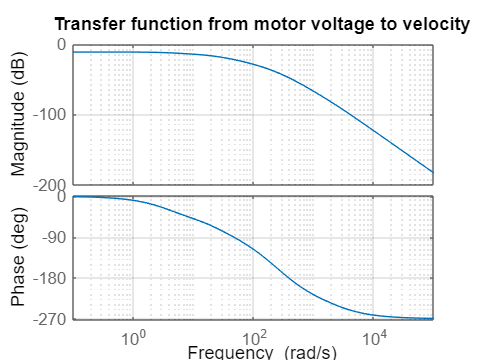

h = figure(100);
bode(Gwv)
grid on
title('Transfer function from motor voltage to velocity')

%saveas(h, 'motor to velocity.png');

## Our work starts here--------------------------------------------

## Voltage to tilt angle 

### Estimate transfer function for base system using LINEARIZE

Motor volatge to angle (va)

load_system(model);
open_system(model);
% define points in model
iosang(1) = linio(strcat(model,'/Step'),1,'openinput');
iosang(2) = linio(strcat(model, '/robot with balance'),1,'openoutput');
% attach to model
setlinio(model,iosang);
% Use the snapshot time(s) 0 seconds
op = [0];
% Linearize the model
sys = linearize(model,iosang,op);
% get transfer function
[numang,denang] = ss2tf(sys.A, sys.B, sys.C, sys.D);
Gva = minreal(tf(numang, denang))

Gva =
 
                                                                                
              -5.893e05 s^4 - 7.71e08 s^3 - 1.435e11 s^2 - 2.566e12 s - 7.683e09
                                                                                
  ------------------------------------------------------------------------------------------
                                                                                            
  s^7 + 2418 s^6 + 1.317e06 s^5 + 1.977e08 s^4 + 1.312e10 s^3 + 1.796e11 s^2 - 9.658e11 s   
                                                                                            
                                                                                  - 1.525e13
                                                                                            
 
Continuous-time transfer function.



### Bodeplot of the tf from vel to tilt angle

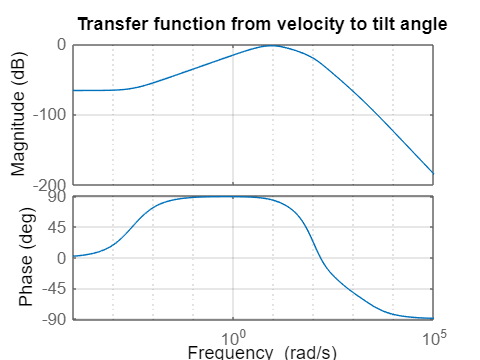

figure(101);
bode(Gva)
grid on
title('Transfer function from velocity to tilt angle')  

### Stabilize the system

Get the bode of the transfer function multiplied by -1

Find the peak in the bode plot

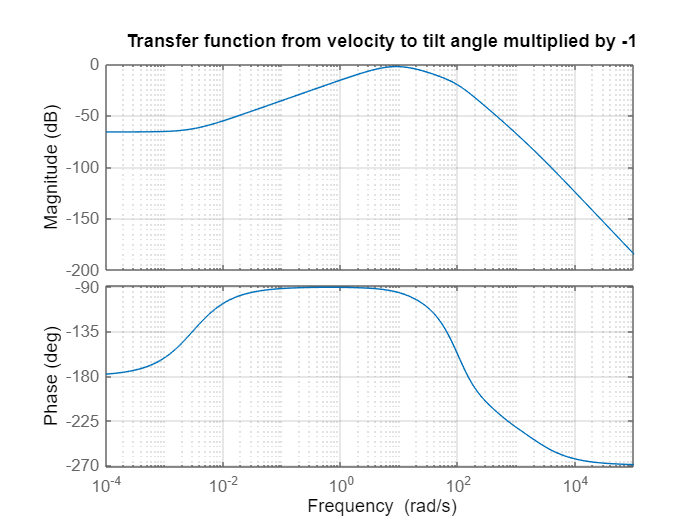

figure();
bode(-1*Gva)
grid on
title('Transfer function from velocity to tilt angle multiplied by -1')

#### Design the I controller to stabilize the system

Implement an I controller right where there is a peak in the bode plot

s = tf('s'); 
%Select the w_i in rad/s -> The PI will be placed at the peak at 10 rad/s
w_i = 10

w_i = 10

tau_i = 1/w_i;
sprintf('Tau_i value to put on REGBOT')

ans = 'Tau_i value to put on REGBOT'

%-----------------------------------------------------------------------------------------------------------
tau_i 

tau_i = 0.1000


% PI controller time constant and transfer function
C_PI = (1 + 1/(tau_i*s));

% Open-loop transfer function
%Remember we carry the -1 we firstly implemented
G_ol = minreal(-C_PI*Gva)

G_ol =
 
                                                                                     
        5.893e05 s^5 + 7.769e08 s^4 + 1.512e11 s^3 + 4e12 s^2 + 2.567e13 s + 7.683e10
                                                                                     
  ------------------------------------------------------------------------------------------
                                                                                            
  s^8 + 2418 s^7 + 1.317e06 s^6 + 1.977e08 s^5 + 1.312e10 s^4 + 1.796e11 s^3 - 9.658e11 s^2 
                                                                                            
                                                                                - 1.525e13 s
                                                                                            
 
Continuous-time transfer function.




%Remember to carry the minus we implemented in the beginning

Stabilizer = -1*C_PI

Stabilizer =
 
  -0.1 s - 1
  ----------
    0.1 s
 
Continuous-time transfer function.



%----------------------------------------------------------------------------------------------------------




%We define a w_c -> We want a good bandwidth
%This actually does nothing
w_c = 2000;                 %How big should it be??

% P-controller gain
K_P = 1/abs(freqresp(G_ol,w_c*1i));

C_PI

C_PI =
 
  0.1 s + 1
  ---------
    0.1 s
 
Continuous-time transfer function.



K_P

K_P = 1.6156e+04

G_ol

G_ol =
 
                                                                                     
        5.893e05 s^5 + 7.769e08 s^4 + 1.512e11 s^3 + 4e12 s^2 + 2.567e13 s + 7.683e10
                                                                                     
  ------------------------------------------------------------------------------------------
                                                                                            
  s^8 + 2418 s^7 + 1.317e06 s^6 + 1.977e08 s^5 + 1.312e10 s^4 + 1.796e11 s^3 - 9.658e11 s^2 
                                                                                            
                                                                                - 1.525e13 s
                                                                                            
 
Continuous-time transfer function.



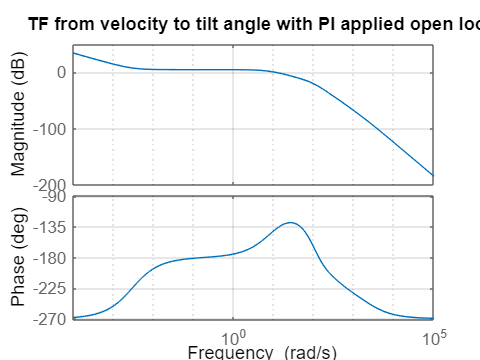




G_cl = minreal(K_P*G_ol/(1 + K_P*G_ol));

figure();
bode(G_ol)
grid on
title('TF from velocity to tilt angle with PI applied open loop')

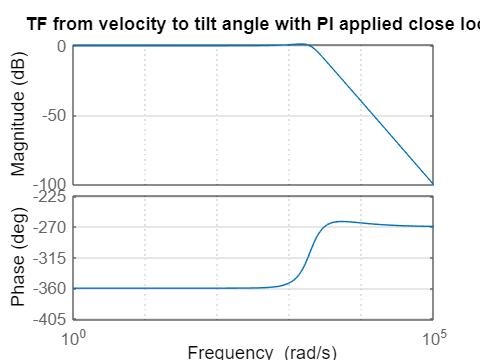


figure();
bode(G_cl)
grid on
title('TF from velocity to tilt angle with PI applied close loop')



stable_G = G_ol         %Define the new tf to work on

stable_G =
 
                                                                                     
        5.893e05 s^5 + 7.769e08 s^4 + 1.512e11 s^3 + 4e12 s^2 + 2.567e13 s + 7.683e10
                                                                                     
  ------------------------------------------------------------------------------------------
                                                                                            
  s^8 + 2418 s^7 + 1.317e06 s^6 + 1.977e08 s^5 + 1.312e10 s^4 + 1.796e11 s^3 - 9.658e11 s^2 
                                                                                            
                                                                                - 1.525e13 s
                                                                                            
 
Continuous-time transfer function.



sprintf('Check the stability of the system cl tf with unit feedback (Kp=1)')

ans = 'Check the stability of the system cl tf with unit feedback (Kp=1)'

sprintf('1 = stable       0 = unstable')

ans = '1 = stable       0 = unstable'

isstable(minreal(1*G_ol/(1 + 1*G_ol)))      %Unit feedback in order to check

ans = logical
   1


[`B`](https://se.mathworks.com/help/control/ref/lti.isstable.html#mw_8d73cc9b-94bd-42ef-a81a-43b420085d2e)` = isstable(`[`sys`](https://se.mathworks.com/help/control/ref/lti.isstable.html#mw_3008ce15-0a87-48d3-b205-3aea109099e9)`)` returns a logical value of `1` (`true`) if the [dynamic system model](https://se.mathworks.com/help/control/ug/dynamic-system-models.html) `sys` has stable dynamics, and a logical value of `0` (`false`) otherwise. If `sys` is a model array, then the function returns `1` only if all the models in `sys` are stable.

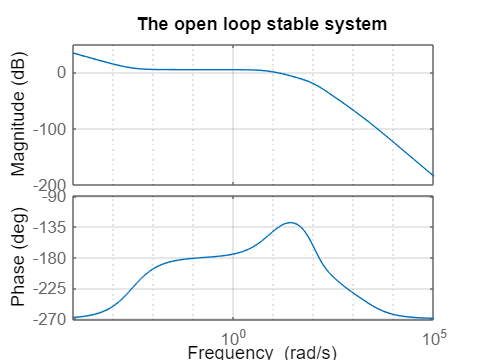

figure;
bode(stable_G)
grid on
title('The open loop stable system')

#### Nyquist plot of our new stable transfer function

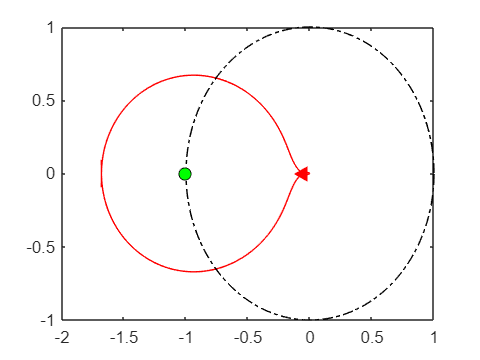

% Nyquist plots for the new tf G_ol
[re_G,im_G,w] = nyquist(G_ol,[-1e4:0.05:1e4]);
re_G = squeeze(re_G);
im_G = squeeze(im_G);
GG_unit = 1*exp(1i*(0:0.001:2*pi));

% Nyquist plots
figure;
plot(re_G,im_G,'r');
hold on;
plot(real(GG_unit),imag(GG_unit),'-.k');
scatter(-1,0,54,'markerFaceColor','g','MarkerEdgeColor','k');
i = find(angle(re_G + 1i*im_G) >= pi/3,1);
scatter(re_G(i),im_G(i),54,'<',...
    'markerFaceColor','r','MarkerEdgeColor','r');
hold off;

## Doing the real controllers

### Tilt controller 

The 'stable_G' is gonna be the new transfer function

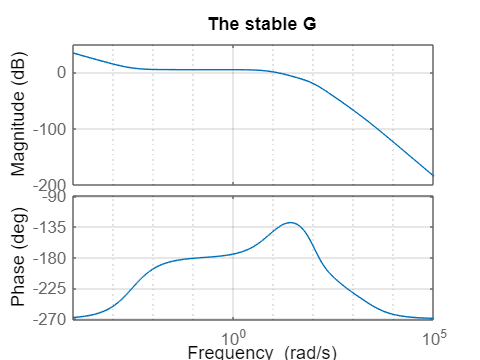

figure;
bode(stable_G)
grid on
title('The stable G')


%We will work on 'stable_G'
s = tf('s');                        % Define complex variable

[MAG_t,PHASE_t,W_t] = bode(stable_G);
MAG_t = mag2db(squeeze(MAG_t));
PHASE_t = squeeze(PHASE_t);
%bode(G);


%Define parameters
phase_margin_t = 75;
N_i_t = 3.5;
alpha_t = 0.2%0.02;

alpha_t = 0.2000


% Calculate the phase of the N_i and alpha (its already in degrees)
phi_i_t = -atand(1/N_i_t);
phi_m_t = asind((1-alpha_t)/(1+alpha_t));

%calculate new phase of G(s)
phase_G_t = phase_margin_t - phi_i_t - phi_m_t - 180

phase_G_t = -130.8649


%Find w_c from the bode plot of G(s) as the frequency at which <G(jwc) = phase_G
id_t = find(PHASE_t >= phase_G_t,1);
w_c_t = W_t(id_t)%+100

w_c_t = 21.1068

%deg2rad(w_c_t)

% We are gonna manually choose the the frequency by looking at the bode plot

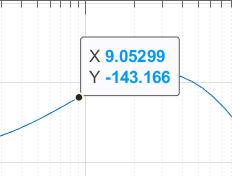

%w_c_t = 3.95

%This frequency (the second one) works better--------------------------------
%w_c_t = 137

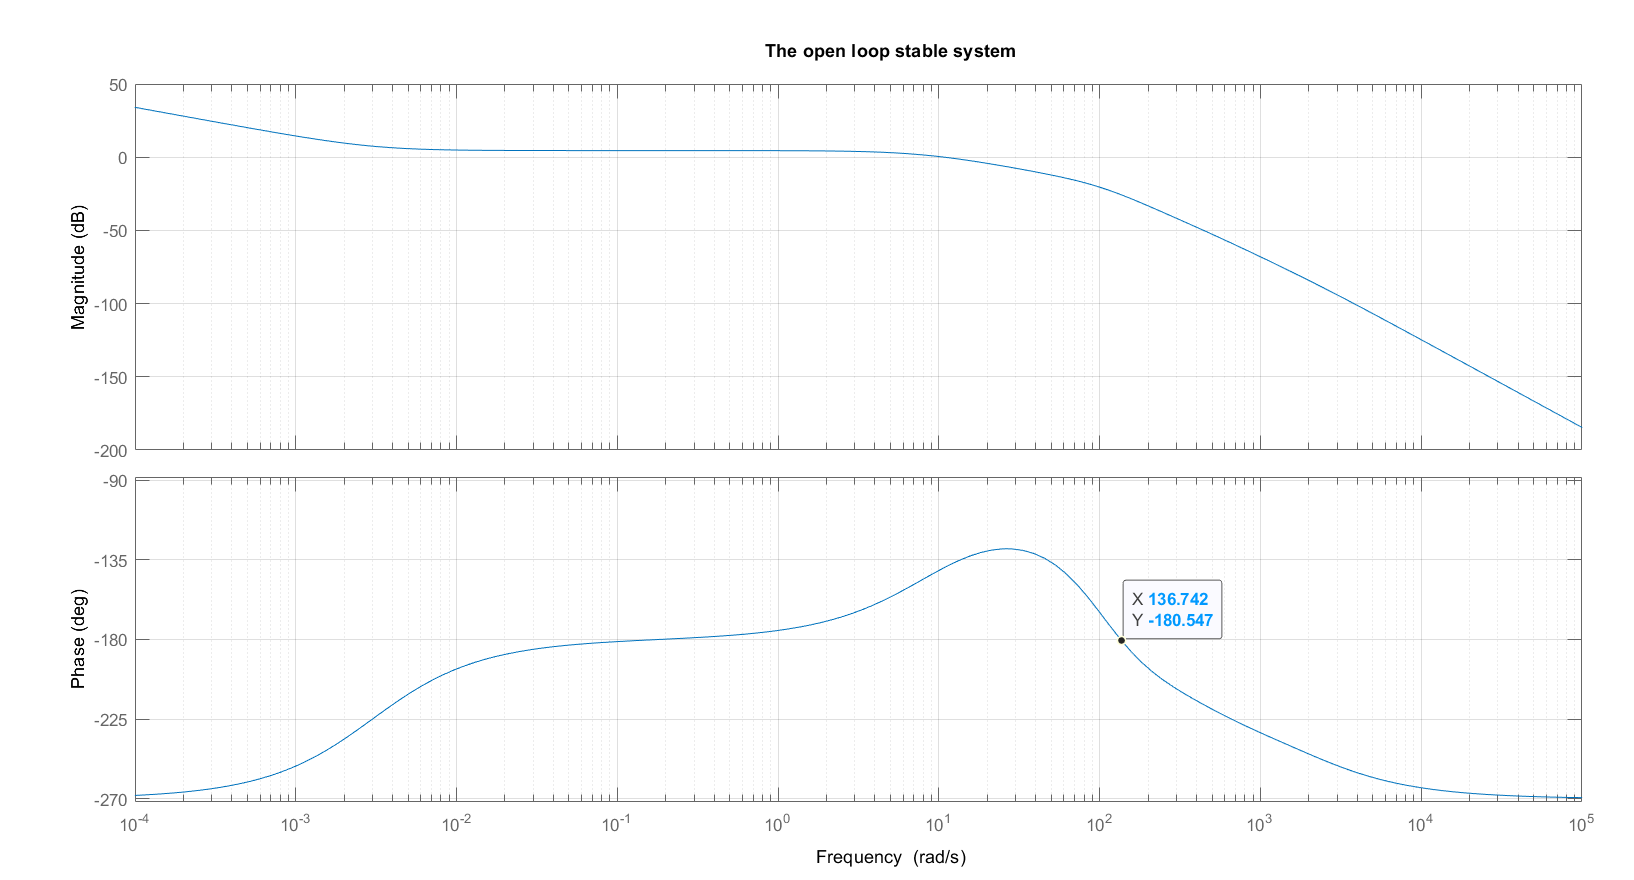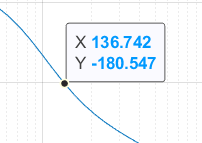

% PI controller time constant and transfer function
tau_i_t = N_i_t/w_c_t;
C_PI_t = (1 + 1/(tau_i_t*s));

% P-Lead controller time constant and transfer function
tau_d_t = 1/(w_c_t*sqrt(alpha_t));
C_D_t = (tau_d_t*s + 1)/(alpha_t*tau_d_t*s + 1);

% Open-loop transfer function
G_ol_t = minreal(C_PI_t*C_D_t*stable_G);

% P-controller gain
K_P_t = 1/abs(freqresp(G_ol_t,w_c_t*1i));

sprintf('Transfer functions for the tilt controller')

ans = 'Transfer functions for the tilt controller'

C_PI_t

C_PI_t =
 
  0.1658 s + 1
  ------------
    0.1658 s
 
Continuous-time transfer function.



C_D_t

C_D_t =
 
  0.1059 s + 1
  -------------
  0.02119 s + 1
 
Continuous-time transfer function.



K_P_t

K_P_t = 0.7323



%-------------------------------------------------------------------------------------------------------------------------
Tilt_KPI = K_P_t*C_PI_t

Tilt_KPI =
 
  0.1214 s + 0.7323
  -----------------
      0.1658 s
 
Continuous-time transfer function.





%bode(G_ol_t)
G_cl_t = minreal(K_P_t*G_ol_t/(1 + K_P_t*G_ol_t));

sprintf('For tilt controller')

ans = 'For tilt controller'

sprintf('K_p value to put on REGBOT')

ans = 'K_p value to put on REGBOT'

K_P_t

K_P_t = 0.7323

sprintf('Tau_i value to put on REGBOT')

ans = 'Tau_i value to put on REGBOT'

tau_i_t

tau_i_t = 0.1658

sprintf('Tau_d value to put on REGBOT')

ans = 'Tau_d value to put on REGBOT'

tau_d_t

tau_d_t = 0.1059

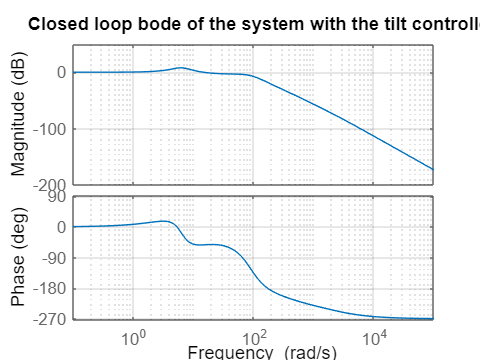

figure;
bode(G_cl_t)
grid on
title('Closed loop bode of the system with the tilt controller')

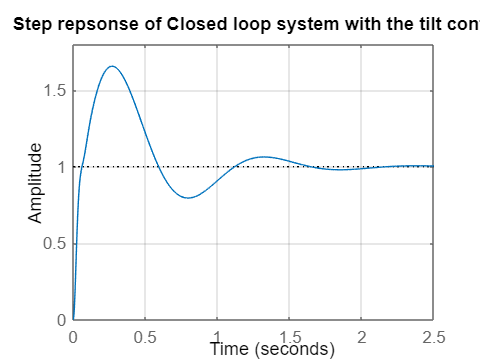


figure;
step(G_cl_t)
grid on
title('Step repsonse of Closed loop system with the tilt controller')

### Velocity controller

Get the new tf from the new model that has the tilt controller implemented

Our input is the angle (recieved by the tilt controller) and the output is wheel velocity (before filtering)

model_t='regbot_1mg_tilt';
load_system(model_t);
open_system(model_t);
% define points in model
iostilt(1) = linio(strcat(model_t,'/Step'),1,'openinput');
iostilt(2) = linio(strcat(model_t, '/robot with balance'),4,'openoutput');
% attach to model
setlinio(model_t,iostilt);
% Use the snapshot time(s) 0 seconds
op_t = [0];
% Linearize the model
sys_t = linearize(model_t,iostilt,op_t);
% get transfer function
[numtilt,dentilt] = ss2tf(sys_t.A, sys_t.B, sys_t.C, sys_t.D);
Ga2v = minreal(tf(numtilt, dentilt))

Ga2v =
 
                                                                                           
  -3.858e04 s^6 - 3.997e07 s^5 - 1.402e09 s^4 - 1.185e10 s^3 + 5.513e10 s^2 + 1.067e12 s   
                                                                                           
                                                                                 + 3.367e12
                                                                                           
  ------------------------------------------------------------------------------------------
                                                                                            
  s^8 + 2218 s^7 + 9.187e05 s^6 + 6.443e07 s^5 + 2.149e09 s^4 + 3.516e10 s^3 + 2.396e11 s^2 
                                                                                            
                                                                    + 5.672e11 s + 1.696e09 
                                                                  

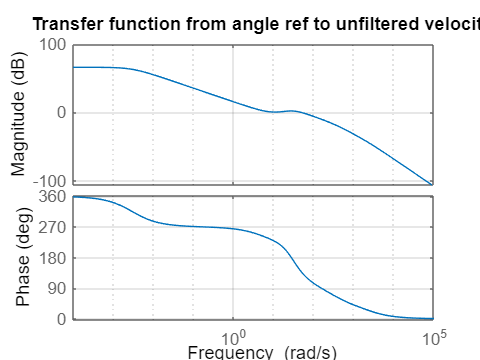

figure;
bode(Ga2v)
grid on
title('Transfer function from angle ref to unfiltered velocity')

#### Creating a filter to suppress the peak of the new tf 

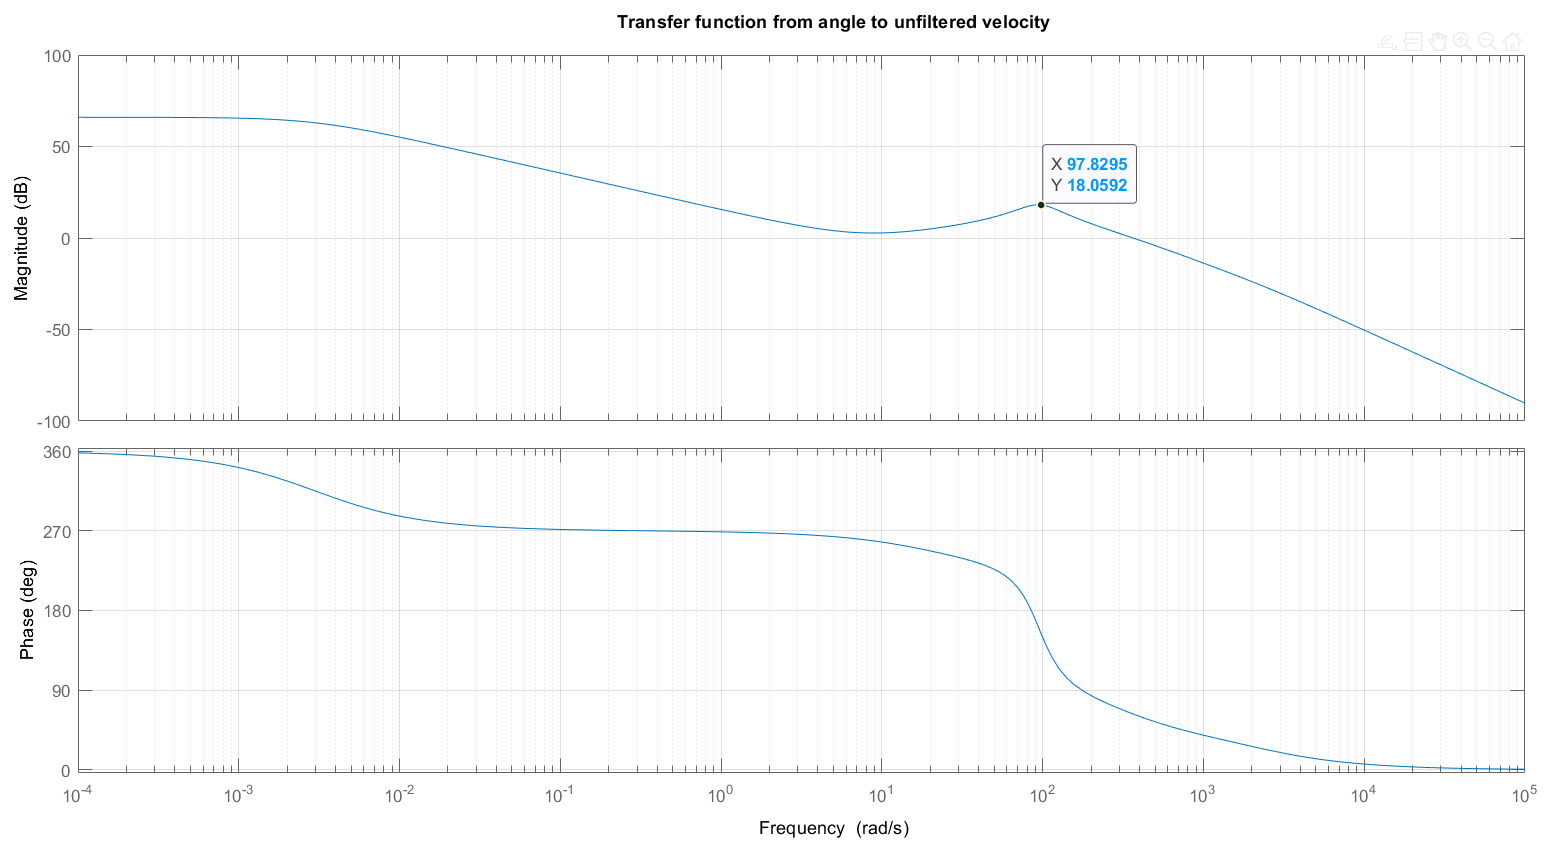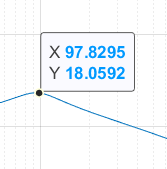


s = tf('s'); 
%Freq to put the filter
v_f_freq = 30.28;
filt_mag = db2mag(12)  %Initially 5     

filt_mag = 3.9811


tau_filt = sqrt(filt_mag^2-1)/v_f_freq 

tau_filt = 0.1273

%first order filter
%vel_filter = v_f_freq/(v_f_freq + s)
vel_filter = 1 /(1 + tau_filt*s)

vel_filter =
 
       1
  ------------
  0.1273 s + 1
 
Continuous-time transfer function.




%Another filter
%Freq to put the filter
v_f_freq_2 = 17;
filt_mag_2 = db2mag(20)  %Initially 5     

filt_mag_2 = 10


tau_filt_2 = sqrt(filt_mag_2^2-1)/v_f_freq_2 

tau_filt_2 = 0.5853

vel_filter = 1 /(1 + tau_filt_2*s)

vel_filter =
 
       1
  ------------
  0.5853 s + 1
 
Continuous-time transfer function.



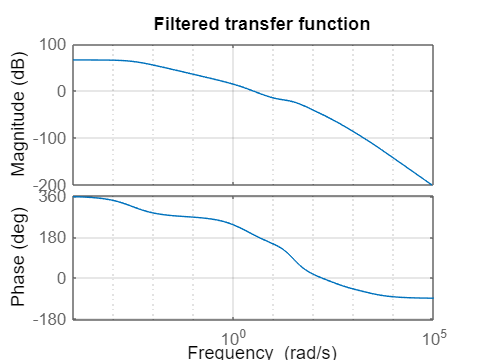

%filtered tf
filtered_Ga2v = Ga2v*vel_filter;
figure;
bode(filtered_Ga2v)
grid on
title('Filtered transfer function')

### Designing the velocity controller

%We will work on 'filtered_Ga2v'
s = tf('s');                        % Define complex variable

[MAG_v,PHASE_v,W_v] = bode(filtered_Ga2v);
MAG_v = mag2db(squeeze(MAG_v));
PHASE_v = squeeze(PHASE_v)-360;     %Because of the way matlab works we substract 360


%Define parameters
phase_margin_v = 85;
N_i_v = 2.9;%3.7
alpha_v = 0.08;%0.08

% Calculate the phase of the N_i and alpha (its already in degrees)
phi_i_v = -atand(1/N_i_v);    
phi_m_v = asind((1-alpha_v)/(1+alpha_v));

%calculate new phase of G(s)
phase_G_v = phase_margin_v - phi_i_v - phi_m_v - 180

phase_G_v = -134.3881


%Find w_c from the bode plot of G(s) as the frequency at which <G(jwc) = phase_G
id_v = find(PHASE_v <= phase_G_v,1);
w_c_v = W_v(id_v)

w_c_v = 1.3169

% deg2rad(w_c_v)
% w_c_v = 3.5%0.6

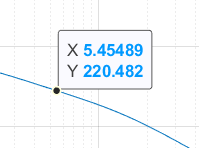

%define our own crossover frequency in rad/s
%w_c_v = 5.45


% PI controller time constant and transfer function
tau_i_v = N_i_v/w_c_v

tau_i_v = 2.2021

C_PI_v = (1 + 1/(tau_i_v*s));



% P-Lead controller time constant and transfer function
tau_d_v = 1/(w_c_v*sqrt(alpha_v))

tau_d_v = 2.6847

C_D_v = (tau_d_v*s + 1)/(alpha_v*tau_d_v*s + 1);

% Open-loop transfer function
G_ol_v = minreal(C_PI_v*C_D_v*filtered_Ga2v);

% P-controller gain
K_P_v = 1/abs(freqresp(G_ol_v,w_c_v*1i));

sprintf('Transfer functions for the velocity controller')

ans = 'Transfer functions for the velocity controller'

C_PI_v

C_PI_v =
 
  2.202 s + 1
  -----------
    2.202 s
 
Continuous-time transfer function.



C_D_v

C_D_v =
 
  2.685 s + 1
  ------------
  0.2148 s + 1
 
Continuous-time transfer function.



K_P_v

K_P_v = 0.0739


Velocity_controller = minreal(K_P_v*C_PI_v*C_D_v)

Velocity_controller =
 
  0.9244 s^2 + 0.7641 s + 0.1564
  ------------------------------
          s^2 + 4.656 s
 
Continuous-time transfer function.



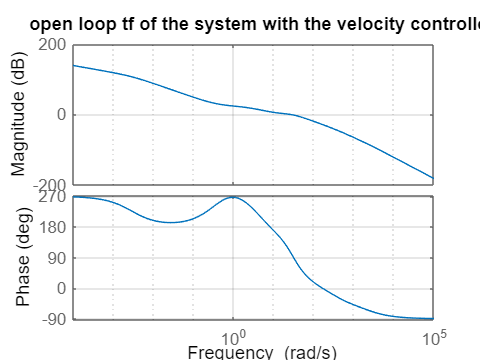



figure;
bode(G_ol_v)
grid on
title('open loop tf of the system with the velocity controller')

G_cl_v = minreal(K_P_v*G_ol_v/(1 + K_P_v*G_ol_v));

sprintf('For velocity controller')

ans = 'For velocity controller'

sprintf('K_p value to put on REGBOT')

ans = 'K_p value to put on REGBOT'

K_P_v

K_P_v = 0.0739

sprintf('Tau_i value to put on REGBOT')

ans = 'Tau_i value to put on REGBOT'

tau_i_v

tau_i_v = 2.2021

sprintf('Tau_d value to put on REGBOT')

ans = 'Tau_d value to put on REGBOT'

tau_d_v

tau_d_v = 2.6847

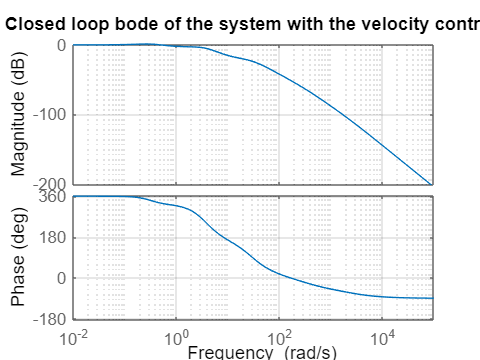



%---------------------
figure;
bode(G_cl_v)
grid on
title('Closed loop bode of the system with the velocity controller')

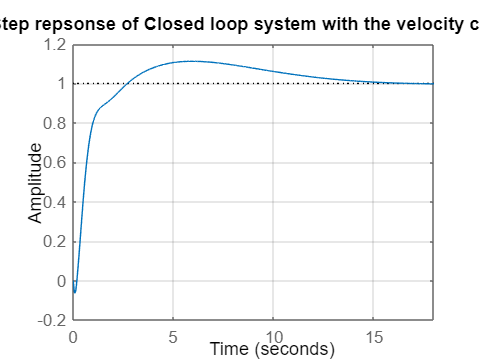


figure;
step(G_cl_v)
grid on
title('Step repsonse of Closed loop system with the velocity controller')

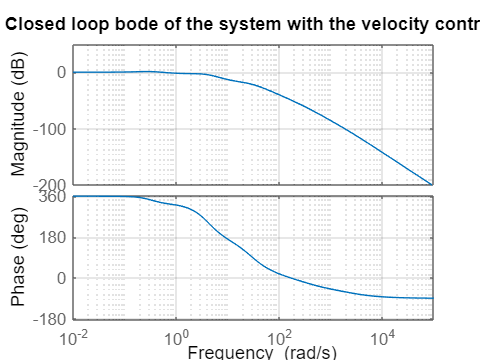

figure;
bode(G_cl_v)
grid on
title('Closed loop bode of the system with the velocity controller')

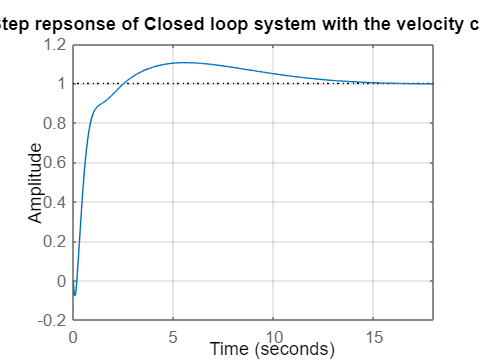


figure;
step(G_cl_v)
grid on
title('Step repsonse of Closed loop system with the velocity controller')

## Position controller

Get the new tf from the new model (regbot_1mg_vel) that has the tilt controller and the velocity controller implemented

Our input is the vel reference (recieved by the vel controller) and the output is the x position

model_v='regbot_1mg_vel';
load_system(model_v);
open_system(model_v);
% define points in model
iosvel(1) = linio(strcat(model_v,'/Step'),1,'openinput');
iosvel(2) = linio(strcat(model_v, '/robot with balance'),3,'openoutput');
% attach to model
setlinio(model_v,iosvel);
% Use the snapshot time(s) 0 seconds
op_v = [0];
% Linearize the model
sys_v = linearize(model_v,iosvel,op_v);
% get transfer function
[numvel,denvel] = ss2tf(sys_v.A, sys_v.B, sys_v.C, sys_v.D);
Gv2pos = minreal(tf(numvel, denvel))

Gv2pos =
 
                                                                                              
    -6.092e04 s^9 - 7.536e07 s^8 - 1.49e10 s^7 - 4.738e11 s^6 - 4.039e12 s^5 + 1.6e13 s^4     
                                                                                              
                                          + 3.575e14 s^3 + 1.35e15 s^2 + 9.371e14 s + 1.799e14
                                                                                              
  ----------------------------------------------------------------------------------------------
                                                                                                
  s^13 + 2425 s^12 + 1.378e06 s^11 + 2.673e08 s^10 + 2.736e10 s^9 + 8.261e11 s^8 + 1.052e13 s^7 
                                                                                                
          + 7.589e13 s^6 + 3.926e14 s^5 + 1.344e15 s^4 + 2.254e15 s^3 + 9.398e14 s^2            
                             

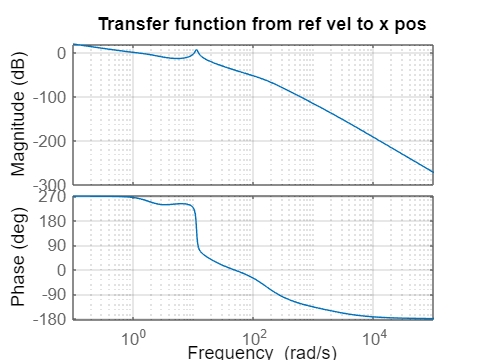

figure;
bode(Gv2pos)
grid on
title('Transfer function from ref vel to x pos')

### Creating a filter for the position controler

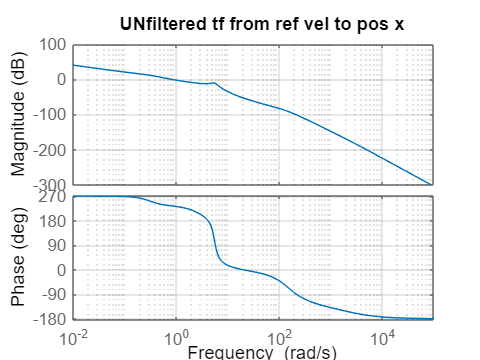

figure
bode(Gv2pos)
grid on
title('UNfiltered tf from ref vel to pos x')


s = tf('s'); 

%Another filter
%Freq to put the filter
p_f_freq_2 = 11.14;
p_filt_mag_2 = db2mag(14)  %Initially 8  then 10   

p_filt_mag_2 = 5.0119


p_tau_filt_2 = sqrt(p_filt_mag_2^2-1)/p_f_freq_2 

p_tau_filt_2 = 0.4409

pos_filter = 1 /(1 + p_tau_filt_2*s)

pos_filter =
 
       1
  ------------
  0.4409 s + 1
 
Continuous-time transfer function.



Gv2pos_filtered = Gv2pos*pos_filter 

Gv2pos_filtered =
 
                                                                                            
  -6.092e04 s^9 - 7.536e07 s^8 - 1.49e10 s^7 - 4.738e11 s^6 - 4.039e12 s^5 + 1.6e13 s^4     
                                                                                            
                                        + 3.575e14 s^3 + 1.35e15 s^2 + 9.371e14 s + 1.799e14
                                                                                            
  ------------------------------------------------------------------------------------------
                                                                                            
  0.4409 s^14 + 1070 s^13 + 6.098e05 s^12 + 1.192e08 s^11 + 1.233e10 s^10 + 3.915e11 s^9    
                                                                                            
          + 5.464e12 s^8 + 4.398e13 s^7 + 2.49e14 s^6 + 9.852e14 s^5 + 2.338e15 s^4         
                                                  

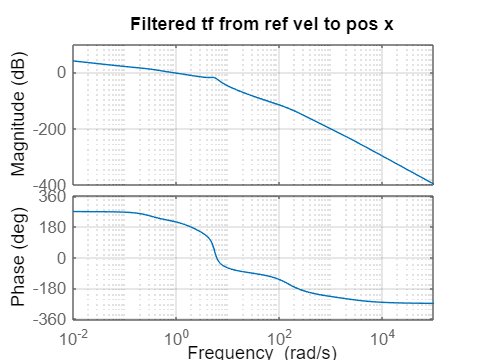


figure
bode(Gv2pos_filtered)
grid on
title('Filtered tf from ref vel to pos x')

### Designing the position controller

%We will work on 'Gv2pos'
s = tf('s');                        % Define complex variable

[MAG_p,PHASE_p,W_p] = bode(Gv2pos_filtered);
MAG_p = mag2db(squeeze(MAG_p));
PHASE_p = squeeze(PHASE_p)-360;


%Define parameters
phase_margin_p = 80;
N_i_p = 2.2;%2.2
alpha_p = 0.05;%0.05

% Calculate the phase of the N_i and alpha (its already in degrees)
phi_i_p = -atand(1/N_i_p);    
phi_m_p = asind((1-alpha_p)/(1+alpha_p));

%calculate new phase of G(s)
phase_G_p = phase_margin_p - phi_i_p - phi_m_p - 180

phase_G_p = -140.3473


%Find w_c from the bode plot of G(s) as the frequency at which <G(jwc) = phase_G
id_p = find(PHASE_p <= phase_G_p,1);
w_c_p = W_p(id_p)

w_c_p = 0.6807

%deg2rad(w_c_p)

%GETTING values way too high for the tau so we may redefine the
%omega-----------------------------------------------------------------------------------------------------------------
%w_c_p = 1

% PI controller time constant and transfer function
tau_i_p = N_i_p/w_c_p;
C_PI_p = (1 + 1/(tau_i_p*s));

% P-Lead controller time constant and transfer function
tau_d_p = 1/(w_c_p*sqrt(alpha_p));
C_D_p = (tau_d_p*s + 1)/(alpha_p*tau_d_p*s + 1);

% Open-loop transfer function
G_ol_p = minreal(C_PI_p*C_D_p*Gv2pos_filtered);

% P-controller gain
K_P_p = 1/abs(freqresp(G_ol_p,w_c_p*1i));

sprintf('Transfer functions for the position controller')

ans = 'Transfer functions for the position controller'

C_PI_p

C_PI_p =
 
  3.232 s + 1
  -----------
    3.232 s
 
Continuous-time transfer function.



C_D_p

C_D_p =
 
   6.57 s + 1
  ------------
  0.3285 s + 1
 
Continuous-time transfer function.



K_P_p

K_P_p = 0.1716


Position_controller = minreal(K_P_p*C_PI_p*C_D_p)

Position_controller =
 
  3.432 s^2 + 1.584 s + 0.1617
  ----------------------------
         s^2 + 3.044 s
 
Continuous-time transfer function.



sprintf('For position controller')

ans = 'For position controller'

sprintf('K_p value to put on REGBOT')

ans = 'K_p value to put on REGBOT'

K_P_p

K_P_p = 0.1716

sprintf('Tau_i value to put on REGBOT')

ans = 'Tau_i value to put on REGBOT'

tau_i_p

tau_i_p = 3.2319

sprintf('Tau_d value to put on REGBOT')

ans = 'Tau_d value to put on REGBOT'

tau_d_p

tau_d_p = 6.5697

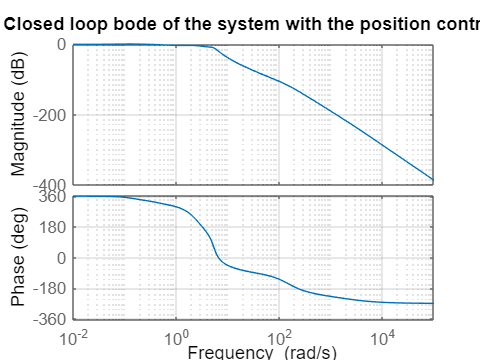

%bode(G_ol_p)
G_cl_p = minreal(K_P_p*G_ol_p/(1 + K_P_p*G_ol_p));
figure;
bode(G_cl_p)
grid on
title('Closed loop bode of the system with the position controller')

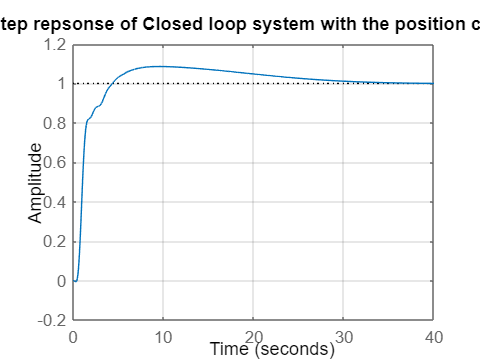



figure;
step(G_cl_p)
grid on
title('Step repsonse of Closed loop system with the position controller')

sprintf('Tau_i value to put on REGBOT for pos intergrator')

ans = 'Tau_i value to put on REGBOT for pos intergrator'

tau_i 

tau_i = 0.1000


sprintf('For tilt controller')

ans = 'For tilt controller'

sprintf('K_p value to put on REGBOT')

ans = 'K_p value to put on REGBOT'

K_P_t

K_P_t = 0.7323

sprintf('Tau_i value to put on REGBOT')

ans = 'Tau_i value to put on REGBOT'

tau_i_t

tau_i_t = 0.1658

sprintf('Tau_d value to put on REGBOT')

ans = 'Tau_d value to put on REGBOT'

tau_d_t

tau_d_t = 0.1059




sprintf('')


ans =

  1×0 empty char array




sprintf('For prefilter to vel tau')

ans = 'For prefilter to vel tau'

tau_filt

tau_filt = 0.1273

sprintf('For velocity controller')

ans = 'For velocity controller'

sprintf('K_p value to put on REGBOT')

ans = 'K_p value to put on REGBOT'

K_P_v

K_P_v = 0.0739

sprintf('Tau_i value to put on REGBOT')

ans = 'Tau_i value to put on REGBOT'

tau_i_v

tau_i_v = 2.2021

sprintf('Tau_d value to put on REGBOT')

ans = 'Tau_d value to put on REGBOT'

tau_d_v

tau_d_v = 2.6847

sprintf('Alpha*Tau_d for the tau_pole')

ans = 'Alpha*Tau_d for the tau_pole'

alpha_v*tau_d_v

ans = 0.2148


sprintf('')


ans =

  1×0 empty char array



sprintf('For prefilter to pos tau')

ans = 'For prefilter to pos tau'

p_tau_filt_2

p_tau_filt_2 = 0.4409

sprintf('For position controller')

ans = 'For position controller'

sprintf('K_p value to put on REGBOT')

ans = 'K_p value to put on REGBOT'

K_P_p

K_P_p = 0.1716

sprintf('Tau_i value to put on REGBOT')

ans = 'Tau_i value to put on REGBOT'

tau_i_p

tau_i_p = 3.2319

sprintf('Tau_d value to put on REGBOT')

ans = 'Tau_d value to put on REGBOT'

tau_d_p

tau_d_p = 6.5697

sprintf('Alpha*Tau_d for the tau_pole')

ans = 'Alpha*Tau_d for the tau_pole'

alpha_p*tau_d_p

ans = 0.3285